Manejo de archivos

clear 
close all
%Creando campo vectorial de un solo iman
magz1=importfile2("CSV/bz_g4");
placeholder=0*magz1;

Definir intervalos

Dimensionamiento del solenoide rectangular

b=5.9;
miu0=4*pi*10^-7;
miu=1500;
l=100*.00064;
N=100;
n=N/l;
i=b/(miu*miu0*n);
disp("Corriente de solenoide rectangular "+i);

Corriente de solenoide rectangular 2.0032


alambre=2*(.038+.019)*100;
disp("Alambre necesario con solenoide rectangular "+alambre+" metros");

Alambre necesario con solenoide rectangular 11.4 metros


ro=1.7*10^-8;
r=ro*alambre/(pi*(.00064/2)^2);
disp("Resistencia del solenoide rectangular "+r+" Ohms");

Resistencia del solenoide rectangular 0.60243 Ohms


potencia=i^2*r;
disp("Potencia de solenoide rectangular "+potencia+" Watts");

Potencia de solenoide rectangular 2.4175 Watts


Dimensionamiento del solenoide con espiras circulares

disp("Corriente de solenoide circular "+i);

Corriente de solenoide circular 2.0032


alambre=.02*pi*100;
disp("Alambre necesario con solenoide de espiras circulares "+alambre+" metros");

Alambre necesario con solenoide de espiras circulares 6.2832 metros


rCircular=ro*alambre/(pi*(.00064/2)^2);
disp("Resistencia del solenoide circular "+r+" Ohms");

Resistencia del solenoide circular 0.60243 Ohms


potenciaCircular=i^2*r;
disp("Potencia de solenoide circular "+potencia+" Watts");

Potencia de solenoide circular 2.4175 Watts


Grafica con solenoide 

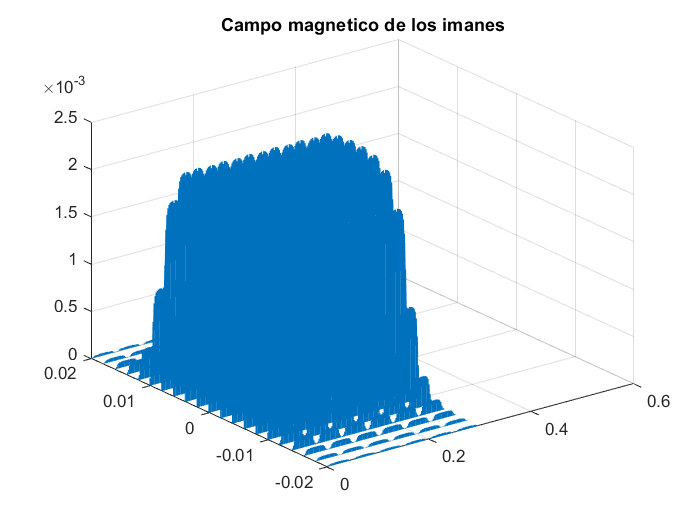

bsolenoide=zeros(21,25);
bsolenoide(6:16,1:25) = -b;
entreimanes=zeros(21,25);



mgzSol=[zeros(21,1),magz1,magz1,magz1,magz1,magz1,magz1,placeholder,placeholder,bsolenoide,placeholder,placeholder,placeholder];
solenoideSolo=[placeholder,placeholder,placeholder,placeholder,placeholder,placeholder,placeholder,placeholder,bsolenoide,placeholder,placeholder,placeholder,zeros(21,1)];
imanessolos=[magz1,magz1,magz1,magz1,magz1,magz1,placeholder,placeholder,placeholder,placeholder,placeholder,placeholder,zeros(21,1)];
dx=.002; 
dy=.002;
xsol=(0:dx:.6);
ysol=(-.020:dy:.020);
[xx,yy]=meshgrid(xsol,ysol);
zz=zeros(size(xx));
magx=zeros(size(xx));
magy=zeros(size(yy));


quiver3(xx,yy,zz,magx,magy,imanessolos)
title("Campo magnetico de los imanes")

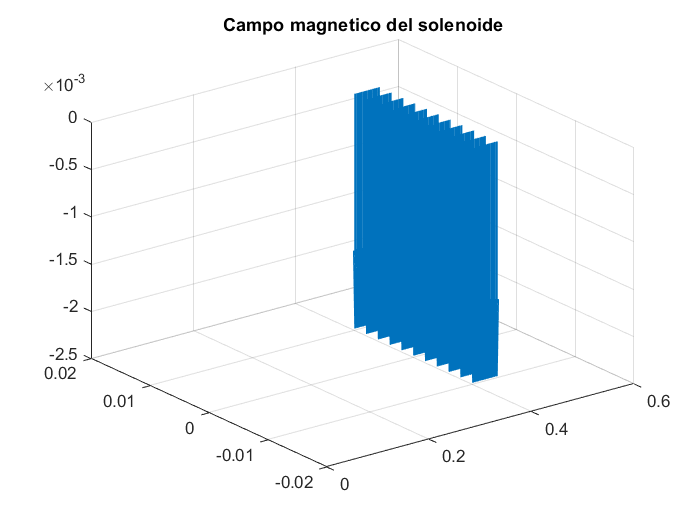


quiver3(xx,yy,zz,magx,magy,solenoideSolo)
title("Campo magnetico del solenoide")

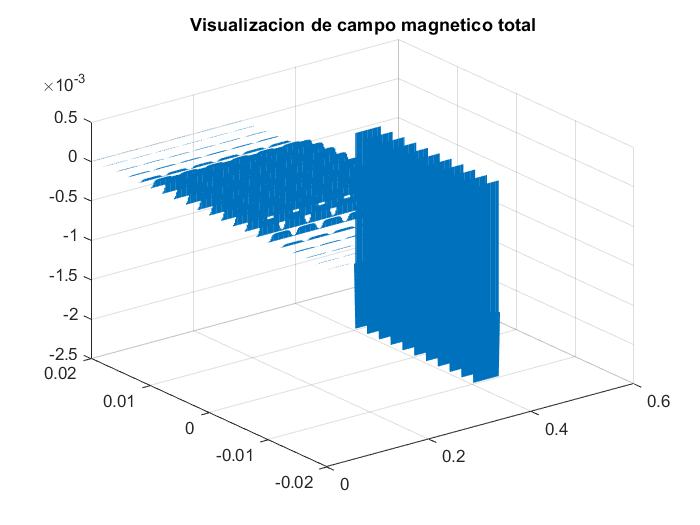


quiver3(xx,yy,zz,magx,magy,mgzSol)
title("Visualizacion de campo magnetico total")

Parametrizacion del circuito en funcion de R fija

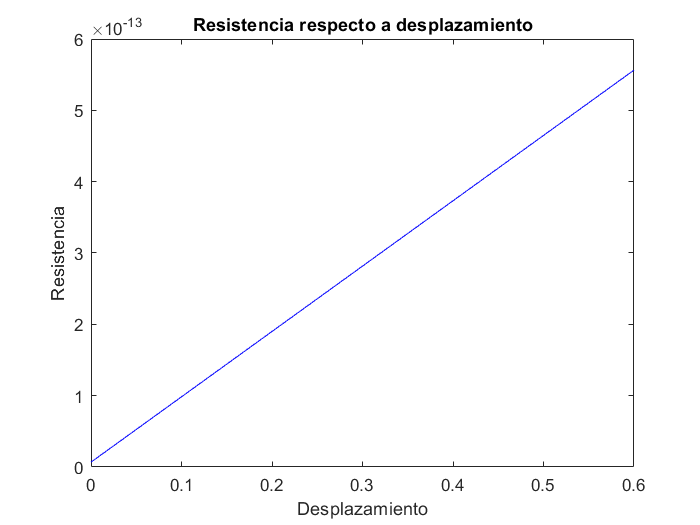

I = 1.5;
V = 1.5;
p = 1.7*10^-8 ;
d11 = 2.3e-3;
h = 0:0.002:0.6;
d14 = 1.62e-3;
r11 = p*(h/(pi/(4*(d11))^2));
r14 = p*(0.03/(pi/(4*(d14))^2));
rf = r14+2*r11;
plot(h, rf, 'b') 
xlabel("Desplazamiento")
ylabel("Resistencia")
title("Resistencia respecto a desplazamiento")

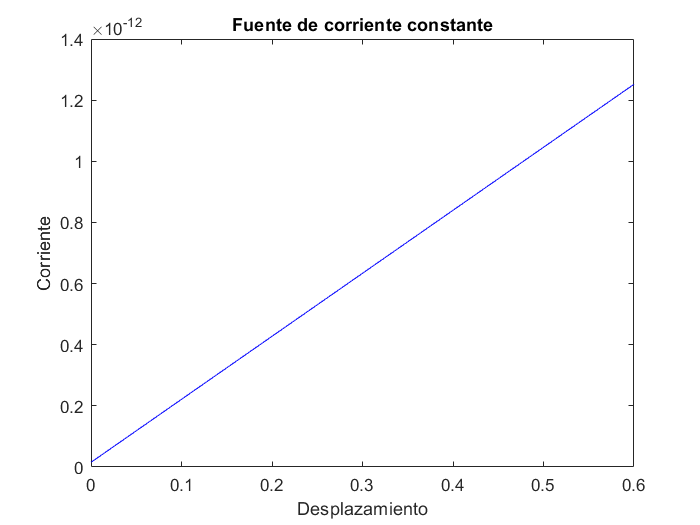

PI = I^2.*rf;
plot(h, PI, 'b') 
xlabel("Desplazamiento")
ylabel("Corriente")
title("Fuente de corriente constante")

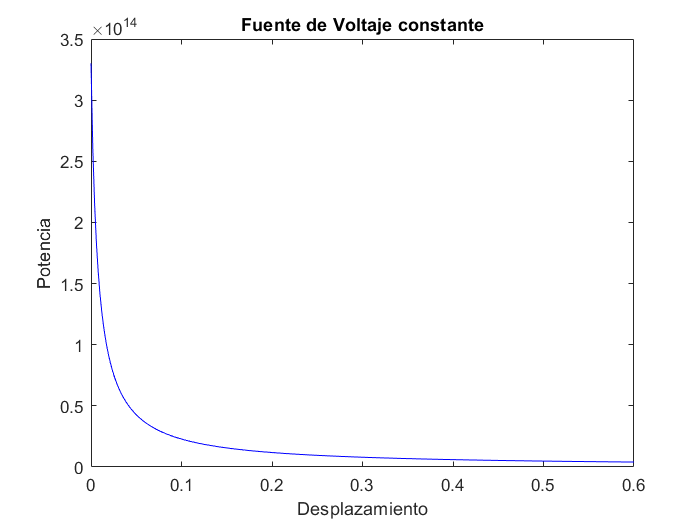

PV = V^2./rf;
plot(h, PV, 'b') 
xlabel("Desplazamiento")
ylabel("Potencia")
title("Fuente de Voltaje constante")

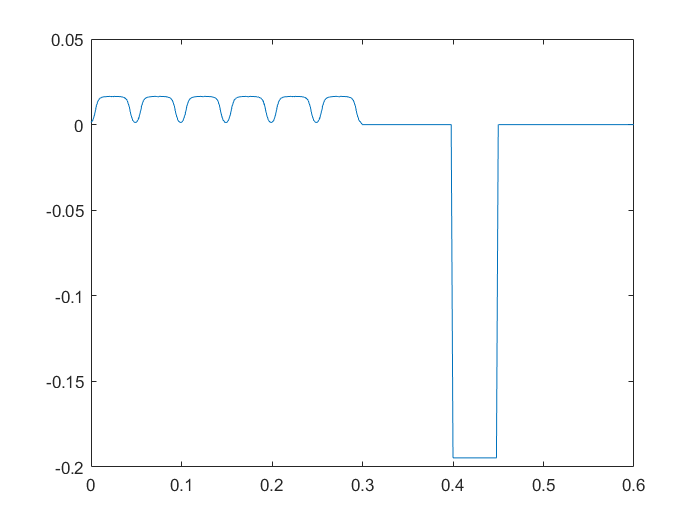

mgzSol2d=[magz1,magz1,magz1,magz1,magz1,magz1,placeholder,placeholder,bsolenoide,placeholder,placeholder,placeholder,zeros(21,1)];
campo2d=trapz(ysol,mgzSol2d*I);
plot(xsol,campo2d)

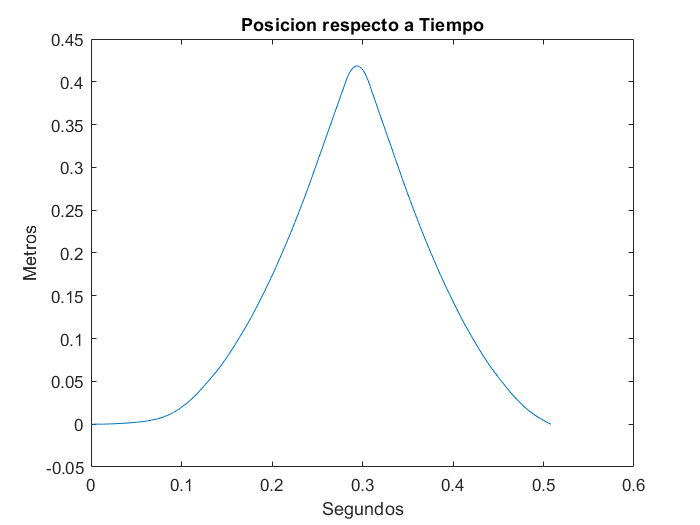

fmag_x=campo2d;  
t=0;
x=xsol;
masa_movil=0.0005592;
dt=0.0001;
muestras=10000;
x_rk=0;
v_rk=0;

for j=1:muestras
    
    k1_x=v_rk(j);
    k1_v=interp1(x,fmag_x,x_rk(j))/(1.5*masa_movil);
    k2_x=v_rk(j);
    k2_v=interp1(x,fmag_x,x_rk(j))/(1.5*masa_movil);
    k3_x=v_rk(j);
    k3_v=interp1(x,fmag_x,x_rk(j))/(1.5*masa_movil);
    k4_x=v_rk(j);
    k4_v=interp1(x,fmag_x,x_rk(j))/(1.5*masa_movil);
    x_rk(j+1)=x_rk(j)+[k1_x+2*(k2_x+k3_x)+k4_x]*dt/6;
    v_rk(j+1)=v_rk(j)+[k1_v+2*(k2_v+k3_v)+k4_v]*dt/6;

    t(j+1)=t(j)+dt;

    if(x_rk(j+1)>0.6)
        break;
    end
end

plot(t,x_rk)
xlabel("Segundos")
ylabel("Metros")
title("Posicion respecto a Tiempo")

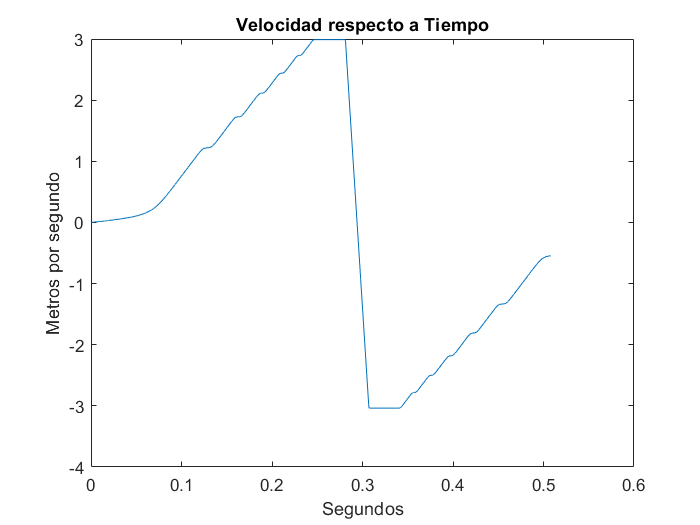

plot(t,v_rk)
title("Velocidad respecto a Tiempo")
ylabel("Metros por segundo")
xlabel("Segundos")